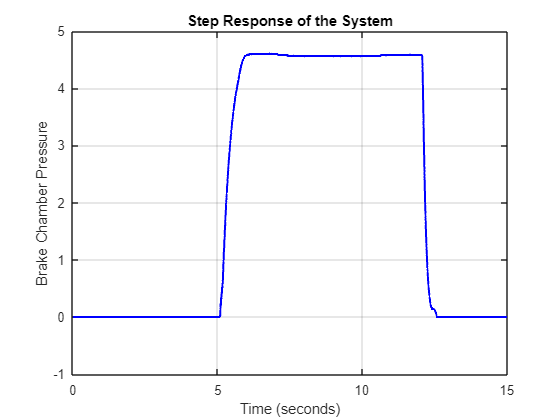



% Assuming the data is stored in a variable named 'stepdata'
% Extract time, input (EPR voltage), and output (brake chamber pressure)
time = stepdata(:, 1);   % First column: Time in seconds
input = stepdata(:, 2);  % Second column: Input (EPR voltage)
output = stepdata(:, 3); % Third column: Output (brake chamber pressure)


% Plot the step response
figure;
plot(time, output, 'b', 'LineWidth', 1.5);
xlabel('Time (seconds)');
ylabel('Brake Chamber Pressure');
title('Step Response of the System');
grid on;

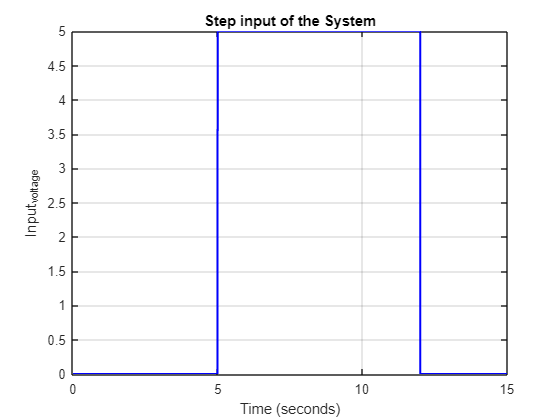


figure;
plot(time, input, 'b', 'LineWidth', 1.5);
xlabel('Time (seconds)');
ylabel('Input_voltage');
title('Step input of the System');
grid on;

K = mean(output(5990 : 7306)) / mean(input(5990 : 7306))

K = 0.9198


% Find the time delay by identifying when the output starts to rise
threshold = 0.01 * max(output); % Set a threshold value
index_tau = find(output > threshold, 1);
tau = time(index_tau)-5

tau = 0.0890


% Estimate the final value of the output
output_final = mean(output(5990 : 7306))

output_final = 4.5990


% Calculate 63% of the final value
output_63 = 0.63 * output_final

output_63 = 2.8974


% Find the time at which the output reaches 63% of its final value
index_T = find(output>=output_63, 1)

index_T = 5415

T = time(index_T)-5.0890 % Subtract the time delay to get the time constant

T = 0.3250


% Create the transfer function with estimated parameters
s = tf('s');
G_estimated = K / (T * s + 1) * exp(-tau * s)

G_estimated =
 
                    0.9198
  exp(-0.089*s) * -----------
                  0.325 s + 1
 
Continuous-time transfer function.
Model Properties


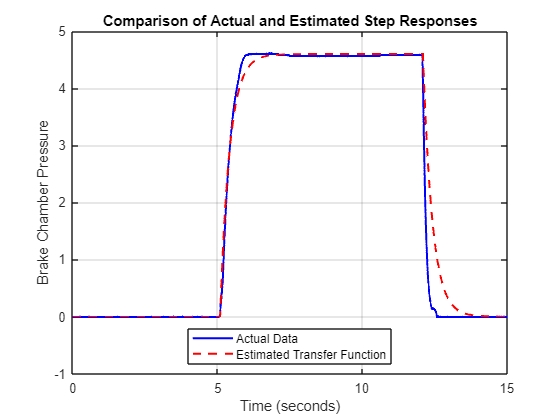


% Simulate the step response of the estimated transfer function
output_signal = lsim(G_estimated , input_signal, time);

% Plot the estimated step response vs. actual data
figure;
plot(time, output, 'b', 'LineWidth', 1.5);
hold on;
plot(time, output_signal, 'r--', 'LineWidth', 1.5);
xlabel('Time (seconds)');
ylabel('Brake Chamber Pressure');
title('Comparison of Actual and Estimated Step Responses');
legend('Actual Data', 'Estimated Transfer Function', 'Location','south');
grid on;


fprintf('Estimated Parameters:\n');

Estimated Parameters:


fprintf('Steady-State Gain (K): %.4f\n', K);

Steady-State Gain (K): 0.9198


fprintf('Time Constant (T): %.4f seconds\n', T);

Time Constant (T): 0.3250 seconds


fprintf('Time Delay (τ): %.4f seconds\n', tau);

Time Delay (τ): 0.0890 seconds
